The original equation is: 


$$\frac{d^2 \phi_n }{{\textrm{dx}}^2 }-\left({\textrm{Kx}}^2 -\epsilon_n \right)\phi_n =0$$


This is the substituion of the equation, and it's: 


$$y_1 =\phi_n \left(x\right)$$



$$y_2 ={\phi_n }^{\prime } \left(x\right)$$


The boundary condition on the left hand side is underdetermined by a parameter, say $A$


$${y_1 =\;\phi }_n \left(-L\right)=A$$



$$y_2 =\;{\phi_n }^{\prime } \left(-L\right)=A\sqrt{L^2 -\epsilon }$$


The solution multiplied by any constants is still good, hence, for any constant $A$ chosen, it will be a good solution, I think that is why we normalizing the function at the end. 

The boundary value on the right hand side that we are trying to solve for is: 


$${\phi_n }^{\prime } \left(L\right)+\sqrt{\;L^2 -\epsilon }\phi_n \left(L\right)=0$$


What are we visualizing? 

Here are some of the suspects, in increasing magnitude of epsilons: 

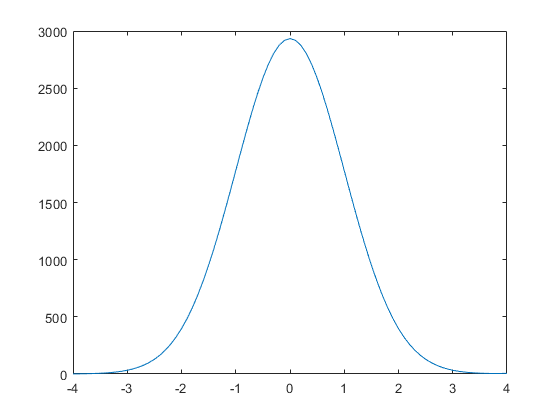

A = 1; L = 4; Epsilon = 0.99983;
y0 = [A, A*sqrt(L^2 - Epsilon)];
Tspan = -L: 0.1: L;

[Xs, Ys] = ode45(@(t, y) Quantum(t, y, Epsilon), Tspan, y0);
plot(Xs, Ys(:, 1));


Ys(end, 2) + sqrt(L^2 - Epsilon)*Ys(end, 1)

ans =   35.658747616019923


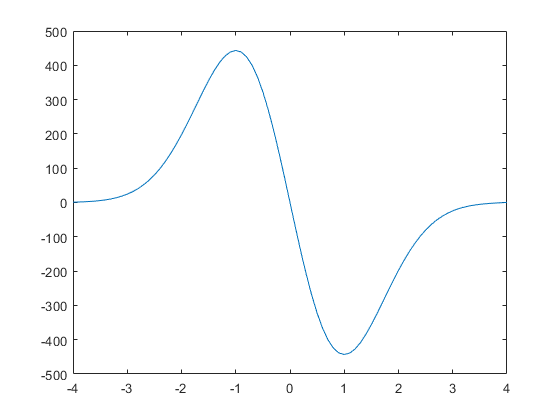

A = 1; L = 4; Epsilon = 2.9995;
y0 = [A, A*sqrt(L^2 - Epsilon)];
Tspan = -L: 0.1: L;

[Xs, Ys] = ode45(@(t, y) Quantum(t, y, Epsilon), Tspan, y0);
plot(Xs, Ys(:, 1));


Ys(end, 2) + sqrt(L^2 - Epsilon)*Ys(end, 1)

ans =    8.490036842241992


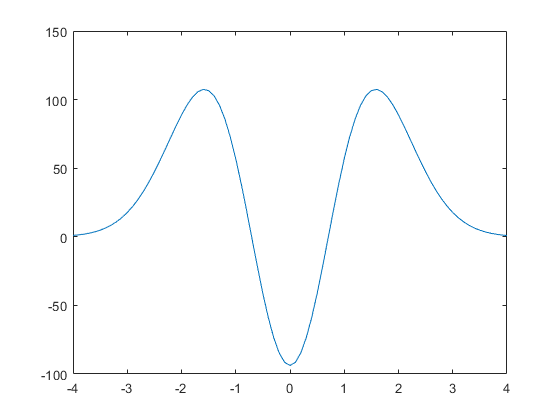

A = 1; L = 4; Epsilon = 4.9993;
y0 = [A, A*sqrt(L^2 - Epsilon)];
Tspan = -L: 0.1: L;

[Xs, Ys] = ode45(@(t, y) Quantum(t, y, Epsilon), Tspan, y0);
plot(Xs, Ys(:, 1));

The modes appears in order, they are not far apart from each other, and they seems to be alternating. 

Therefore, the previous modes will be used as initial conditions to shoot for the next one, but reverse the stepping conditions. 

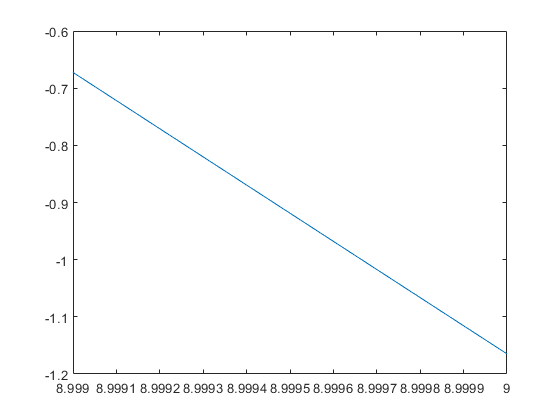

Xlinspace = linspace(8.999, 9, 1000);
plot(Xlinspace, RHSDV(Xlinspace));

Let's plot this functon out. 

Interesting we can solve for the fzero right? 

[x, fval] = fzero(@RHSDV, 9);
x

x = 8.9976

fval

fval = 3.1246e-12

RHSDV(8.999942335700617)

ans = -1.1365

#### Problem 2

For Problem 2 the equation I have comes from the PPT from the TA,, say that our operation matrix is $A$, then it's setup as $A\phi =\left(\epsilon \Delta x^2 \right)\phi$; we can also multiply both side by $\epsilon$ to make life easier. 

And the eigen values are just the $\epsilon \;\Delta x^2$, and the boundary conditiosn is: 


$${\phi_n }^{\prime } \left(-L\right)-\sqrt{\;L^2 -\epsilon }\phi_n \left(-L\right)=0$$
 

for the left hand side, and for the right hand side: 


$${\phi_n }^{\prime } \left(L\right)+\sqrt{\;L^2 -\epsilon }\phi_n \left(L\right)=0$$


Make it simplier by using $B=\sqrt{\;L^2 -\epsilon }$

The Boundary is non-linear, thence for this HW, it's assume to be that: 


$$h\sqrt{\;L^2 -\epsilon_{n\;} }\approx 0$$


giving us: 


$${\phi_n }^{\prime } \left(\pm L\right)=0$$


Hence on the boundary, we have the following: 


$$3\phi_{n\;} \left(x_0 \right)=4\phi_n \left(x_1 \right)-\phi_n \left(x_2 \right)$$



$$3\phi_{n\;} \left(x_n \right)=4\phi_n \left(x_{n-1} \right)-\phi_n \left(x_{n-2} \right)$$


And then this equation together with the broken forward and backward difference is going to be the first and the last row of the matrix.

#### Problem 3

The non-linear system is like: $\frac{d^2 \phi_n }{{\mathrm{dx}}^2 }-\left(\gamma \;|\phi_n |^2 +{K\;x}^2 -\epsilon_n \right)\phi_n =0$

We apply the subsitution: 


$$y_1 =\phi_n$$



$$y_2 ={\phi_n }^{\prime }$$


Taking the derivative and making the substitution gives: 


$${y_1 }^{\prime } ={\phi_n }^{\prime } =y_2$$



$${y_2 }^{\prime } ={{\phi_n }^{\prime } }^{\prime } =\left(\gamma |y_1 |^2 +K\;x^2 -\epsilon_n \right)y_1$$


And this is the system of equation we are going to double shoot for. 

Here is the initial conditions: 

The boundary is set to be $K=1$,$L=2$. and $\gamma =\pm 0\ldotp 05$

For this problem, we are shooting a solution for the boundary value problem for 2 modes of $\gamma \;\ldotp \;$

The initial condition is:


$$y_0 =\left\lbrack A,A\sqrt{\;K\;L^2 -\epsilon_n }\right\rbrack$$


We tweak the value of $A$ until the norm of the funciton becomes 1, so that it's a probability density funciton, after that we shoot for the value of $\epsilon_n$ until the boundary value is satisfied. 

We are only look for the first 2 eigen functions. 

The QunatumDoubleShoot function will do the shooting with given value $A,\epsilon ,\gamma \;$ to shoot and then return the norm of function, returning the norm and the boundary satisfaction indictors. 

gamma = 0.05; epsilon = 2, a = 1; 

epsilon = 2

Let's only tweak the value for y to shoot solve for $A$. 

f = @(a) QuantumDoubleShoot(a, epsilon, 0.05) - 1; 
[a, fval] = fzero(f, 1)

a = 0.1810

fval = -3.3307e-16

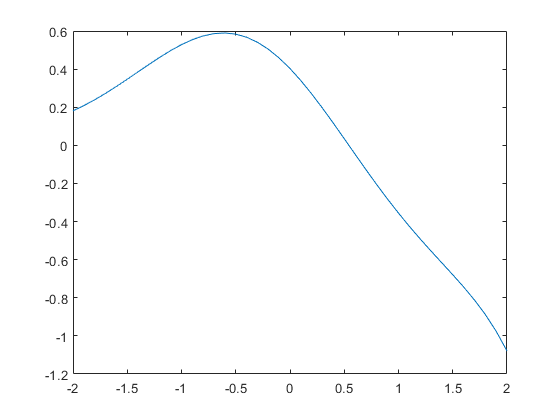

[~, ~, Solution] = QuantumDoubleShoot(a, epsilon, gamma);
plot(-2: 0.1: 2, Solution);

a

a = 0.1810

f = @(epsilon) ShootForEpsilon(a, epsilon, 0.05);
[epsilon, boundary] = fzero(f, 3);
epsilon 

epsilon = 2.9213

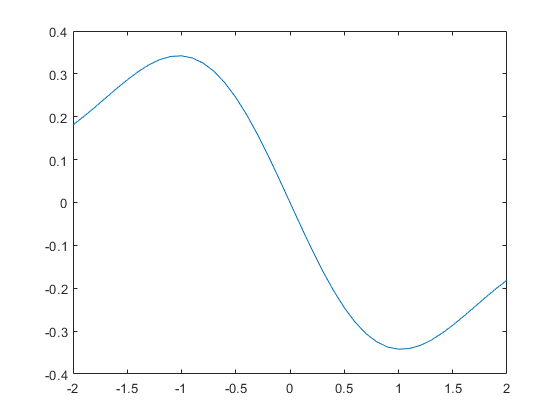

[FxnNorm, Boundary, Solution] = QuantumDoubleShoot(a, epsilon, 0.05);
plot(-2: 0.1: 2, Solution);

FxnNorm, Boundary

FxnNorm = 0.5275

Boundary = 2.2204e-16

Ok, we need to find the signs of things when we shoot for the parameter $A$. That means we are going to plot a lot of things. I suspect the interval for is slucked in between 0.2 to 0.4, and this is going to be the inverval for plotting the function. 

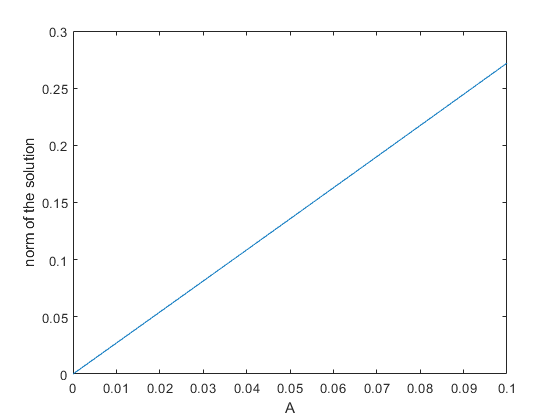

Xaxis = linspace(0, 0.1, 100);
Yaxis = [];
for x = Xaxis
    [FxnNorm, ~, ~] = QuantumDoubleShoot(x, 3, 0.05);
    Yaxis(end + 1) = FxnNorm;
end
plot(Xaxis, Yaxis)
ylabel("norm of the solution")
xlabel("A")

function Boundary = ShootForEpsilon(a, epsilon, gamma)
    [~, Boundary, ~] = QuantumDoubleShoot(a, epsilon, gamma);
end